# Natural Frenet Frame

The other modlues in this series are

[**Introduction**](matlab:open('./Introduction.mlx'))**: **An interactive lesson on the definition of parametric equations, frames, and group transformations, all from the point of view of curves and trajectories as vector-valued parametric functions.

[**Fernet Serret frame**](matlab:open('./Frenet_Serret_Frames.mlx'))**: **An interactive lesson on the Frenet Serret frame, which is the most commonly used and known moving frame method. Applications include generating trajectories using parameters like curvature and torsion in mechanical systems such as multi-link manipulators and unicycle models.

[**Natural Frenet frame**](matlab:open('./Natural_Frenet_Frames.mlx'))**: **An interactive lesson on the natural Frenet frame, where its similarities and differences with the Frenet-Serret frame are compared.

**Before you get started:**

- This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.  

- The plots at each section of this Live Script are built upon variables that might be created in the previous sections. To get the intended visuals and results, run the sections consecutively.  

 
clc; clear;

## Defining the Natural Frenet Frame

Recall that when constructing the Frenet-Serret frame, the curve needed to satisfy a certain condition: the  *nondegeneracy* ($\kappa > 0$) of the framed curve $r(t)$. We would like to find an alternative frame without this strict requirement, namely the *Natural-Frenet Frame*, which was constructed by Richard Bishop in his seminal paper "There is More than One Way to Frame a Curve" (1975).

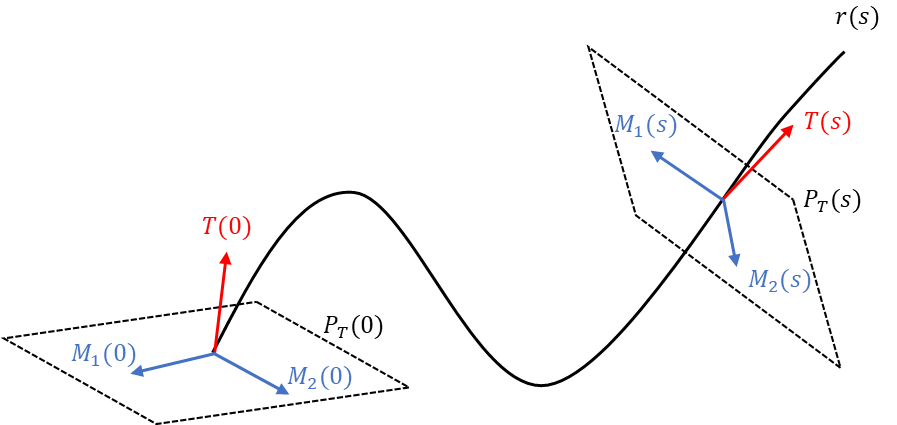

Let $r(s)$ denote a regular curve in $\mathbb{R}^3$ parametrized by an arc-length parameter $s$. Let $T(0)$ be the unit tangent vector of $r$ at $s = 0$. We can define $P_T(0)$ as the plane normal to $T(0)$, and choose a basis $\{M_1(0), M_2(0)\}$ for $P_T(0)$ such that $\{T(0), M_1(0), M_2(0)\}$ form a **right handed orthonormal frame**. 

Here are three properties of the triple $\{T(0), M_1(0), M_2(0)\}$:

1.        $\{T(0), M_1(0), M_2(0)\}$ is *right handed,* i.e. $M_2(0) = T(0) \times M_1(0)$.

2.        Since $T(0)$ is a unit vector, we know that 

        
$$\begin{array}{rcl}
T(0)\cdot T(0) &=& 1 \\
\Longrightarrow T'(0)\cdot T(0) &=& 0\\
\Longrightarrow T'(0) & \in & P_T(0)
\end{array}
$$


        In other words, there exists constants $k_1(0)$ and $k_2(0)$ such that 

        
$$T'(0) = k_1(0)M_1(0) + k_2(0)M_2(0)$$


        We call $k_1(0)$ and $k_2(0)$ the *natural curvatures* of the curve at $s = 0$.

3.        From normality, we know that $M_i(0)\cdot T(0) = 0$ for $i = 1, 2$. Then,

        
$$\Longrightarrow M'_i(0) \cdot T(0) = -M_i(0) \cdot T'(0) \\ 
\ \ \ \ \ \ \ \ \ \ \ \ \ = -M_i(0)  \cdot(k_1(0)M_1(0) + k_2(0) M_2(0)) \\
\ \ \ \ \ \ \ \ \ \ \ \ \ = -k_i(0)$$


            In other words, 


$$M'_1(0) = -k_1(0)T(0)$$



$$M'_2(0) = -k_2(0)T(0)$$


We wish to find the propagation of a triple $\{T(s), M_1(s), M_2(s)\}$ such that the above properties remain satisfied for all $s$.  This leads to the definition of the *Natural Frenet frame:*

An orthonormal triad $\{T(s), M_1(s), M_2(s)\}$is a set of *Natural Frenet frames* or *relatively parallel adapted frames* (RPAF) along a curve $r(s)$ if there exists natural curvature functions $k_1(\cdot)$ and $k_2(\cdot)$ such that


$$T' = k_1M_1 + k_2M_2$$



$$M_1' = -k_1T$$



$$M_2' = -k_2T$$


Given an initial choice of the basis $\{M_1(0), M_2(0)\}$, there is a unique natural Frenet frame along $r$ for that choice. The proof for uniqueness follows from the existence-uniqueness of ordinary differential equations for specified curvature functions, which themselves are determined by the geometry of the curve. 

    *Note*: Integrating $M_1' $ and $M_2'$ shows that the curvature functions are determined by Volterra Integral equations


$$k_1(s) = T'(s)\cdot M_1(0) - \int_0^s k_1(\sigma)T'(s)\cdot T(\sigma)d\sigma$$



$$k_2(s) = T'(s)\cdot M_2(0) - \int_0^s k_2(\sigma)T'(s)\cdot T(\sigma)d\sigma$$


                    which can be solved to give unique solutions given an initial frame $\{M_1(0), M_2(0)\}$.

Let's take a look at how the natural Frenet frame (for a given initial $\{M_1(0), M_2(0)\}$) propagates compared to the Frenet-Serret frame for a helix curve:

Ex. 

Note: If the animations are causing slowdowns or not working correctly, uncheck the "animation" box for a simplified view of the module.

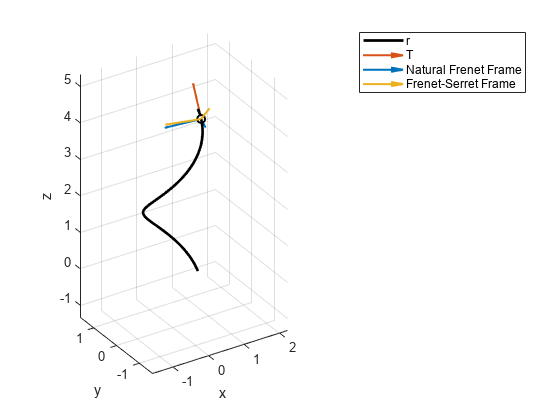

aFlag = true; 
syms t;
% generate curve and frames
x(t) = sqrt(2)/2*cos(t);
y(t) = sqrt(2)/2*sin(t);
z(t) = sqrt(2)/2*t;
r = [x; y; z];
r_dot = diff(r);
s_dot = simplify(sqrt(r_dot.'*r_dot));
T = r_dot/s_dot;
dT = diff(T)/s_dot;
kappa = simplify(sqrt(dT.'*dT));
Normal = simplify(dT/kappa);
B = simplify(cross(T, Normal));

M1_0 = [sqrt(2)/2; -1/2; 1/2];
M2_0 = cross(double(T(0)), M1_0);
dB = diff(B)/s_dot;
tau = simplify(-dB.'*Normal);
s(t) = int(s_dot, 0, t);
theta(t) = atan2(double(dT(0).'*M2_0), double(dT(0).'*M1_0)) + int(tau, 0, s(t));
k1(t) = kappa*cos(theta);
k2(t) = kappa*sin(theta);

M1(t) = M1_0 + int(-k1*T, 0, s);
M2(t) = M2_0 + int(-k2*T, 0, s);

% convert from symbolic to vector
tspan = linspace(0, 2*pi, 50);
numr = double(cell2sym(r(tspan)));
numT = double(cell2sym(T(tspan)));
numM1 = double(cell2sym(M1(tspan)));
numM2 = double(cell2sym(M2(tspan)));
numN = double(cell2sym(Normal(tspan)));
numB = double(cell2sym(B(tspan)));

% plot
figure
x = numr(1, :);
y = numr(2, :);
z = numr(3, :);
plot3(x, y, z,'k','LineWidth',2)
hold on

axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;    
qT = quiver3(x(1), y(1), z(1), numT(1, 1), numT(2, 1), numT(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1.5);
qM1 = quiver3(x(1), y(1), z(1), numM1(1, 1), numM1(2, 1), numM1(3, 1), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qM2 = quiver3(x(1), y(1), z(1), numM2(1, 1), numM2(2, 1), numM2(3, 1), quiverSize ,'SeriesIndex', 1, 'LineWidth',1.5);
qN = quiver3(x(1), y(1), z(1), numN(1, 1), numN(2, 1), numN(3, 1), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);
qB = quiver3(x(1), y(1), z(1), numB(1, 1), numB(2, 1), numB(3, 1), quiverSize ,'SeriesIndex', 3, 'LineWidth',1.5);
qU = quiver3(x(1), y(1), z(1), 0, 0, 0, 'o', 'LineWidth',1.5, 'MarkerEdgeColor', 'k', 'MarkerFaceColor', 'w');
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
grid on
view([-32.5 30])
xlabel('x')
ylabel('y')
zlabel('z')
legend(["r","T", "Natural Frenet Frame", NaN, "Frenet-Serret Frame"])

% animate
if aFlag
    for i=1:length(x)-2
      ax.View = [-32.5, 30];
    
      qT.XData = x(i);
      qT.YData = y(i);
      qT.ZData = z(i);
      qT.UData = numT(1, i);
      qT.VData = numT(2, i);
      qT.WData = numT(3, i);
    
      qM1.XData = x(i);
      qM1.YData = y(i);
      qM1.ZData = z(i);
      qM1.UData = numM1(1, i);
      qM1.VData = numM1(2, i);
      qM1.WData = numM1(3, i);
    
      qM2.XData = x(i);
      qM2.YData = y(i);
      qM2.ZData = z(i);
      qM2.UData = numM2(1, i);
      qM2.VData = numM2(2, i);
      qM2.WData = numM2(3, i);
    
      qN.XData = x(i);
      qN.YData = y(i);
      qN.ZData = z(i);
      qN.UData = numN(1, i);
      qN.VData = numN(2, i);
      qN.WData = numN(3, i);
    
      qB.XData = x(i);
      qB.YData = y(i);
      qB.ZData = z(i);
      qB.UData = numB(1, i);
      qB.VData = numB(2, i);
      qB.WData = numB(3, i);
    
      qU.XData = x(i);
      qU.YData = y(i);
      qU.ZData = z(i);
      qU.UData = 0;
      qU.VData = 0;
      qU.WData = 0;
      
      drawnow 
      
    end
end
hold off

## Natural Frenet Frame and Frenet-Serret Frame

If the curve is nondegenerate, then there exists an interesting relation between the natural Frenet frame and the Frenet-Serret frame. From the definition of the Frenet-Serret frame we see that 


$$N(s) = \frac{T'(s)}{\kappa(s)}$$


                                    
$$= \frac{k_1(s)M_1(s)+k_2(s)M_2(s)}{\kappa(s)}$$


Therefore


$$ N(s)\cdot N(s) = \frac{k_1^2(s) + k_2^2(s)}{\kappa^2(s)}$$


And since $N(s)\cdot N(s) \equiv 1$, we have


$$\kappa(s) = \sqrt{k_1^2(s)+k_2^2(s)}$$


    *Note*: Classical curvature $\kappa$ is always positive, so we can throw away the negative solution.

Similar calculations can be done to show that the torsion of the curve is given by


$$\tau(s) = \frac{k'_2k_1 - k'_1k_2}{k_1^2+k^2_2}$$


                
$$=\frac{d\left(\tan^{-1}\left(\frac{k_2}{k_1}\right)\right)}{ds}$$



$$:=\theta'(s)$$


By defining $\theta$ in this manner, the term can be thought of as a polar angle in the $(k_1, k_2)$ plane, and from the earlier calculation see that $(\kappa, \theta)$ can in fact represent polar coordinates on this plane, which we now define as the plane of normal development. We also define the trajectories made by $(k_1(s), k_2(s))$ on this plane the normal development of the curve $r(s)$.

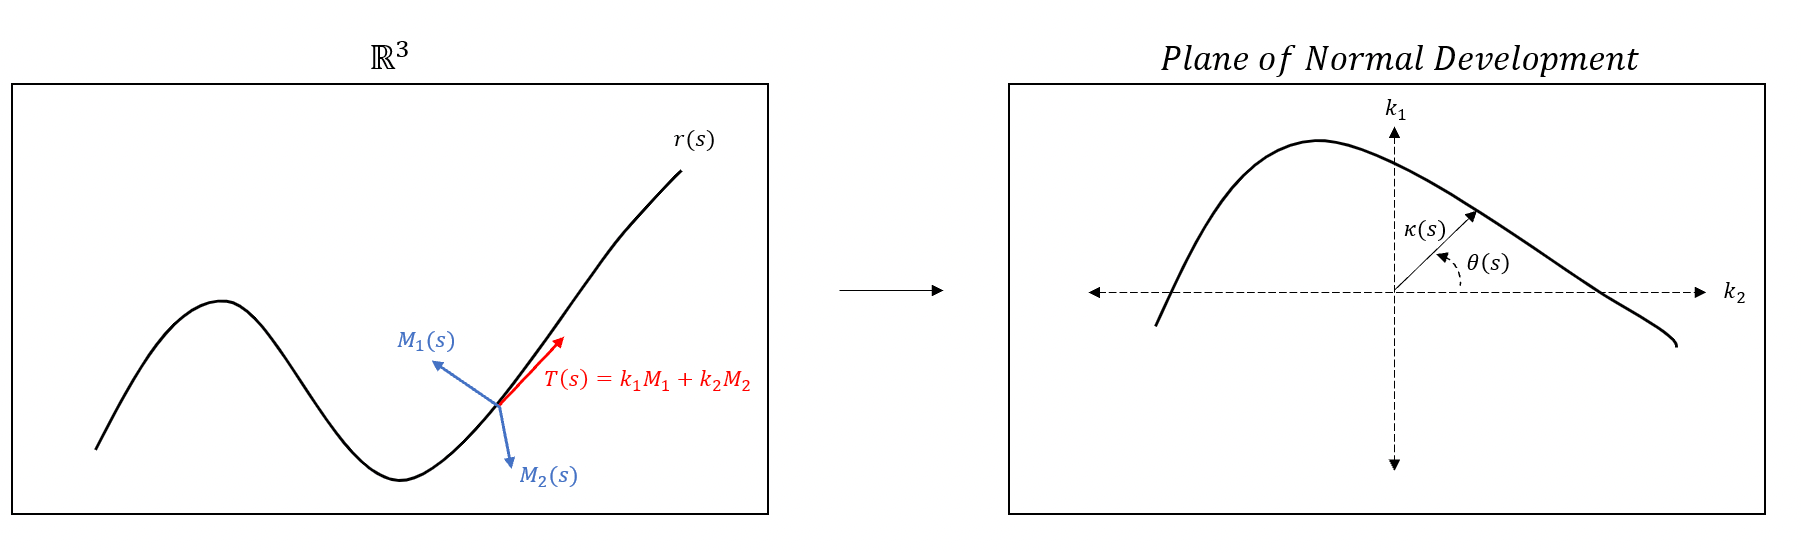

From the definition of $\theta(s)$, we see that 


$$k_1\sin(\theta) = k_2\cos(\theta)$$


which implies that


$$N(s) = \cos(\theta(s))\,M_1(s) + \sin(\theta(s))\,M_2(s)$$



$$B(s) = -\sin(\theta(s))\,M_1(s) + \cos(\theta(s))\,M_2(s)$$


from the fact that $T'(s) = k_1(s)\, M_1(s) + k_2(s)\, M_2(s)$. So we can think of $\theta$ as the accumulated rotation or phase shift of the $\{N(s), B(s)\}$ frame relative to the $\{M_1(s), M_2(s)\}$ frame.

Similar to the Frenet-Serret frames, the natural Frenet frames are invariant under Euclidean transformations. This means that the normal development of the curve is also invariant under these transformations. 

## Natural Frenet Frames for Curves on a Sphere

Consider a curve $r(s)$ lying on a sphere of radius $R$ centered around the point $p$. Then we know


$$(r(s) - p)\cdot (r(s) - p) \equiv R^2$$


differentiating both sides, we get 


$$(r(s)-p)\cdot T(s) \equiv 0$$


differentiate again and we find that


$$(r(s) - p)\cdot T'(s) \equiv -1$$



$$(r(s)-p)\cdot(k_1(s)M_1(s)+k_2(s)M_2(s)) \equiv -1$$


but we know that 


$$M'_i(s)\cdot (r(s)-p) = -k_iT\cdot (r(s)-p)$$


    
$$\equiv 0$$
 

So $M_i\cdot (r(s)-p) \equiv c_i$ some constant for $i = 1, 2$.

Thus, we have


$$c_1k_1(s) + c_2k_2(s) \equiv -1$$


i.e. the normal development lies on a line not passing through the origin. 

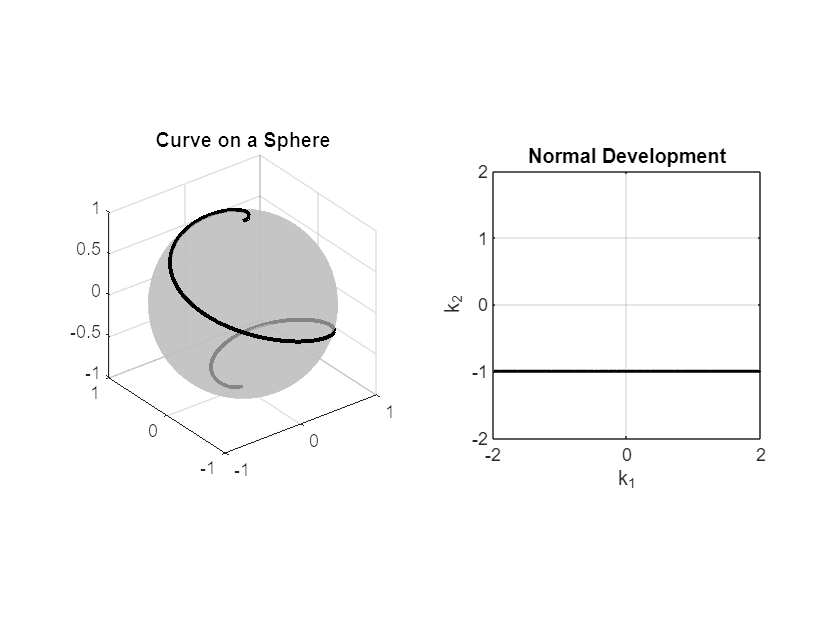

%clear;
 %plotting sphere
figure
tL = tiledlayout(1,2);
theta = 2*pi*(0:50)/50;
phi   = 2*pi*(0:50)'/50;
x = sin(phi)*cos(theta);
y = sin(phi)*sin(theta);
z = cos(phi)*ones(size(theta));
nexttile
p = mesh(x,y,z, 'FaceAlpha', .7);
title('Curve on a Sphere')
p.FaceColor = 'interp';
p.LineStyle = 'none';
colormap([.75 .75 .75]);
axis square
hold on

%calculating k1, k2
syms t
r(t) = [sin(t)*cos(3*t); sin(t)*sin(3*t); cos(t)];
r_dot = diff(r);
s_dot = simplify(sqrt(r_dot.'*r_dot));
T = simplify(r_dot/s_dot);
dT = simplify(diff(T)/s_dot);
kappa = simplify(sqrt(dT.'*dT));
Normal = simplify(dT/kappa);
B = simplify(cross(T, Normal));

e1 = [0; 1; 0];
M1_0 = e1 - T(0)'*e1/norm(T(0))^2*T(0);
M1_0 = double(M1_0/norm(M1_0));
M2_0 = double(cross(T(0), M1_0));
dB = diff(B)/s_dot;
tau = simplify(-dB.'*Normal);
s(t) = int(s_dot, 0, t);
theta = atan2(double(dT(0).'*M2_0), double(dT(0).'*M1_0)) + int(tau*s_dot, 0, t);
k1(t) = kappa*cos(theta);
k2(t) = kappa*sin(theta);

tspan = linspace(0, pi, 200);
numr = double(cell2sym(r(tspan)));
nums = double(s(tspan));
numtheta_dot = double(tau(tspan).*s_dot(tspan));
numtheta = atan2(double(dT(0).'*M2_0), double(dT(0).'*M1_0)) + cumtrapz(tspan, numtheta_dot);

%calculating k1, k2 symbolically (DONT USE)
% symk1 = double(k1(tspan));
% symk2 = double(k2(tspan));

%calculating k1, k2 numerically
numk1 = double(kappa(tspan).*cos(numtheta));
numk2 = double(kappa(tspan).*sin(numtheta));

% trapzk1 = trapez(r, M1_0, tspan);
% trapzk2 = trapez(r, M2_0, tspan);

%plotting normal development
x = numr(1, :);
y = numr(2, :);
z = numr(3, :);
plot3(x, y, z,'k','LineWidth',2)
hold off
nexttile
plot(numk1, numk2,'k','LineWidth',1.5)
xlabel('k_1')
ylabel('k_2')
axis square
axis([-2 2 -2 2])
grid on
title('Normal Development')


%Calculating error
% errk1 = norm(symk1 - numk1);
% errk2 = norm(symk2 - numk2);

Expanding $(r(s) - p)$


$$(r(s)-p) = ((r(s)-p)\cdot M_1)M_1 + ((r(s) - p)\cdot M_2)M_2 + ((r(s)-p)\cdot T)T$$



$$= c_1M_1+c_2M_1$$


Then, $R^2 = c_1^2+c_2^2$, and we see that the normal development lies on a line that is a distance of $\frac{1}{R}$ from the origin.

*Note*: Since the normal development is invariant to Euclidean transformations, it contains no information on the center of the sphere $p$.

## Computer Graphics

An important fact regarding the natural Frenet frame is that it is that frame which minimizes rotation about the tangent. In other words, the curve swept out by the $M_1$ and $M_2$ vectors are parallel to the original curve. This is desirable in fields such as computer animation, where it would be useful to require a camera to remain in some fixed skew orientation relative to the camera path (for example, animating the gaze of a passenger looking out of an airplane window or a first person view of a thrilling roller coaster ride). All such applications are easily accommodated using the natural Frenet frame applied to an initial camera orientation.

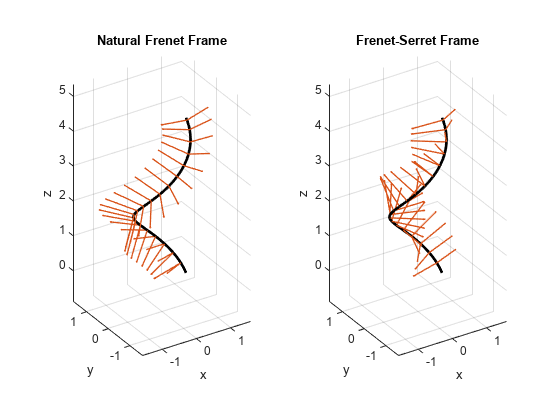

clear x y z r;
 
%calculate the frames
aFlag=true;
syms t;
x(t) = sqrt(2)/2*cos(t);
y(t) = sqrt(2)/2*sin(t);
z(t) = sqrt(2)/2*t;
r(t) = [x; y; z];
r_dot = diff(r);
s_dot = simplify(sqrt(r_dot.'*r_dot));
T = r_dot/s_dot;
dT = diff(T)/s_dot;
kappa = simplify(sqrt(dT.'*dT));
Normal = simplify(dT/kappa);
B = simplify(cross(T, Normal));

e1 = [0; 1; 0];
M1_0 = e1 - T(0)'*e1/norm(T(0))^2*T(0);
M1_0 = double(M1_0/norm(M1_0));
M2_0 = double(cross(T(0), M1_0));
dB = diff(B)/s_dot;
tau = simplify(-dB.'*Normal);
s(t) = int(s_dot, 0, t);

% convert to vectors
tspan = linspace(0, 2*pi, 200);
nums = double(s(tspan));
nums_dot = double(s_dot(tspan));
numtheta_dot = double(tau(tspan).*s_dot(tspan));
numtheta = atan2(double(dT(0).'*M2_0), double(dT(0).'*M1_0)) + cumtrapz(tspan, numtheta_dot);
numk1 = double(kappa(tspan).*cos(numtheta));
numk2 = double(kappa(tspan).*sin(numtheta));
numr = double(cell2sym(r(tspan)));
numT = double(cell2sym(T(tspan)));
numN = double(cell2sym(Normal(tspan)));
numB = double(cell2sym(B(tspan)));
numM1 = zeros(3, 200);
numM2 = zeros(3, 200);
for i = 1:3
    numM1(i, :) = M1_0(i) + cumtrapz(nums, -numk1.*numT(i,:));
    numM2(i, :) = M2_0(i) + cumtrapz(nums, -numk2.*numT(i,:));
end

% plot
figure
tL = tiledlayout(1,2);
ax1 = nexttile;
x = numr(1, :);
y = numr(2, :);
z = numr(3, :);
plot3(x, y, z,'k','LineWidth',2)
hold on

axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;   
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
grid on
view([-32.5 30])
qM1 = quiver3(x(1), y(1), z(1), numM1(1, 1), numM1(2, 1), numM1(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
qM2 = quiver3(x(1), y(1), z(1), numM2(1, 1), numM2(2, 1), numM2(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
title('Natural Frenet Frame');
xlabel('x');
ylabel('y');
zlabel('z');
ax2 = nexttile;
plot3(x, y, z,'k','LineWidth',2)
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;   
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
hold on
qN = quiver3(x(1), y(1), z(1), numN(1, 1), numN(2, 1), numN(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
qB = quiver3(x(1), y(1), z(1), numB(1, 1), numB(2, 1), numB(3, 1), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
grid on
view([-32.5 30])
title('Frenet-Serret Frame');
xlabel('x');
ylabel('y');
zlabel('z');

% animate
if aFlag
    for i=1:length(x)-2
      hold on
      if mod(i, 10) == 0
        quiver3(ax1, x(i), y(i), z(i), numM1(1, i), numM1(2, i), numM1(3, i), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
        quiver3(ax1, x(i), y(i), z(i), numM2(1, i), numM2(2, i), numM2(3, i), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
        quiver3(ax2, x(i), y(i), z(i), numN(1, i), numN(2, i), numN(3, i), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
        quiver3(ax2, x(i), y(i), z(i), numB(1, i), numB(2, i), numB(3, i), quiverSize ,'SeriesIndex', 2, 'LineWidth',1);
      end
      qM1.XData = x(i);
      qM1.YData = y(i);
      qM1.ZData = z(i);
      qM1.UData = numM1(1, i);
      qM1.VData = numM1(2, i);
      qM1.WData = numM1(3, i);
    
      qM2.XData = x(i);
      qM2.YData = y(i);
      qM2.ZData = z(i);
      qM2.UData = numM2(1, i);
      qM2.VData = numM2(2, i);
      qM2.WData = numM2(3, i);
    
      qN.XData = x(i);
      qN.YData = y(i);
      qN.ZData = z(i);
      qN.UData = numN(1, i);
      qN.VData = numN(2, i);
      qN.WData = numN(3, i);
    
      qB.XData = x(i);
      qB.YData = y(i);
      qB.ZData = z(i);
      qB.UData = numB(1, i);
      qB.VData = numB(2, i);
      qB.WData = numB(3, i);
      
      drawnow 
      
    end
end
hold off

Another very useful application in computer graphics is that smooth objects can be generated or rendered by sweeping some shape along a chosen trajectory using the natural Frenet frame. The example below illustrates sweeping an ellipse defined in both the Frenet-Serret frame and the natural Frenet frame along some curve. The resulting surface in the Frenet-Serret frame case contains many twists and turns, which might not be desirable for an animator or designer.

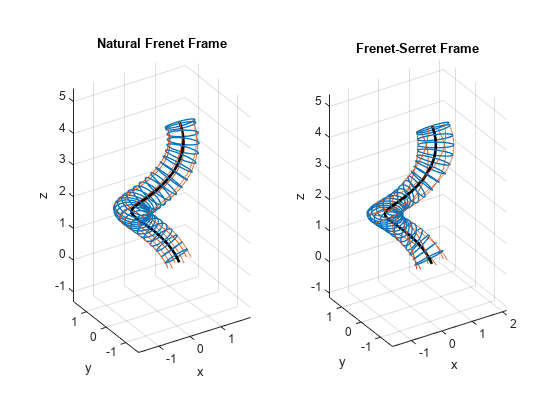

clear x y z r;
 
%caluclate the frames
aFlag=true;
syms t;
x(t) = sqrt(2)/2*cos(t);
y(t) = sqrt(2)/2*sin(t);
z(t) = sqrt(2)/2*t;
r(t) = [x; y; z];
r_dot = diff(r);
s_dot = simplify(sqrt(r_dot.'*r_dot));
T = r_dot/s_dot;
dT = diff(T)/s_dot;
kappa = simplify(sqrt(dT.'*dT));
Normal = simplify(dT/kappa);
B = simplify(cross(T, Normal));

e1 = [0; 1; 0];
M1_0 = e1 - T(0)'*e1/norm(T(0))^2*T(0);
M1_0 = double(M1_0/norm(M1_0));
M2_0 = double(cross(T(0), M1_0));
dB = diff(B)/s_dot;
tau = simplify(-dB.'*Normal);
s(t) = int(s_dot, 0, t);

% convert to vectors
tspan = linspace(0, 2*pi, 200);
nums = double(s(tspan));
nums_dot = double(s_dot(tspan));
numtheta_dot = double(tau(tspan).*s_dot(tspan));
numtheta = atan2(double(dT(0).'*M2_0), double(dT(0).'*M1_0)) + cumtrapz(tspan, numtheta_dot);
numk1 = double(kappa(tspan).*cos(numtheta));
numk2 = double(kappa(tspan).*sin(numtheta));
numr = double(cell2sym(r(tspan)));
numT = double(cell2sym(T(tspan)));
numN = double(cell2sym(Normal(tspan)));
numB = double(cell2sym(B(tspan)));
numM1 = zeros(3, 200);
numM2 = zeros(3, 200);
for i = 1:3
    numM1(i, :) = M1_0(i) + cumtrapz(nums, -numk1.*numT(i,:));
    numM2(i, :) = M2_0(i) + cumtrapz(nums, -numk2.*numT(i,:));
end

% plot
tspanelps = linspace(0, 2*pi, 50);
figure
tL = tiledlayout(1,2);
ax1 = nexttile;
x = numr(1, :);
y = numr(2, :);
z = numr(3, :);
plot3(numr(1, :), numr(2, :), numr(3, :),'k','LineWidth',2)
hold on
elps1(t) = numr(:, 1) + .5*cos(t)*numM1(:, 1)+.3*sin(t)*numM2(:, 1);
numelps1 = double(cell2sym(elps1(tspanelps)));
p1 = plot3(numelps1(1, :), numelps1(2, :), numelps1(3, :), 'SeriesIndex', 1, 'LineWidth',1);
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;   
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
grid on
view([-32.5 30])

title('Natural Frenet Frame');
xlabel('x');
ylabel('y');
zlabel('z');
ax2 = nexttile;
plot3(x, y, z,'k','LineWidth',2);
hold on
elps2(t) = numr(:, 1) + .5*cos(t)*numN(:, 1)+.3*sin(t)*numB(:, 1);
numelps2 = double(cell2sym(elps2(tspanelps)));
p2 = plot3(numelps2(1, :), numelps2(2, :), numelps2(3, :), 'SeriesIndex', 1, 'LineWidth',1);
axis equal
ax = gca;
quiverSize = max([range(ax.XLim) range(ax.YLim) range(ax.ZLim)])/5;   
[XLim, YLim, ZLim] = padax(ax, quiverSize, 1);
ax.XLim = XLim;
ax.YLim = YLim;
ax.ZLim = ZLim;
grid on
view([-32.5 30])
title('Frenet-Serret Frame');
xlabel('x');
ylabel('y');
zlabel('z');

% animate
if aFlag
    for i=1:length(x)-2
      hold on
      elps1(t) = numr(:, i) + .5*cos(t)*numM1(:, i)+.3*sin(t)*numM2(:, i);
      numelps1 = double(cell2sym(elps1(tspanelps)));
      elps2(t) = numr(:, i) + .5*cos(t)*numN(:, i)+.3*sin(t)*numB(:, i);
      numelps2 = double(cell2sym(elps2(tspanelps)));
      trails1 = double(cell2sym(elps1([0, pi/3, 2*pi/3, pi, 4*pi/3, 5*pi/3])));
      trails2 = double(cell2sym(elps2([0, pi/3, 2*pi/3, pi, 4*pi/3, 5*pi/3])));
      plot3(ax1, trails1(1, :), trails1(2, :), trails1(3, :), '.', 'SeriesIndex', 2, 'MarkerSize', .5);
      plot3(ax2, trails2(1, :), trails2(2, :), trails2(3, :), '.', 'SeriesIndex', 2, 'MarkerSize', .5);
      if mod(i, 7) == 0
        plot3(ax1, numelps1(1, :), numelps1(2, :), numelps1(3, :), 'SeriesIndex', 1, 'LineWidth',1);
        plot3(ax2, numelps2(1, :), numelps2(2, :), numelps2(3, :), 'SeriesIndex', 1, 'LineWidth',1);
      end
      p1.XData = numelps1(1, :);
      p1.YData = numelps1(2, :);
      p1.ZData = numelps1(3, :);
    
      p2.XData = numelps2(1, :);
      p2.YData = numelps2(2, :);
      p2.ZData = numelps2(3, :);
      drawnow 
      
    end
end
hold off


%Numerical
% r_dot = gradient(r);
% r_dot(1) = NaN;
% r_dot(end) = NaN;
% s_dot = vecnorm(r_dot);
% T = r_dot./s_dot;
% dT = gradient(T)/dt./s_dot;
% dT(abs(dT)<1e-4) = 0; %sanitize underflows
% Normal = dT./vecnorm(dT);
% B = cross(T,Normal);
% 
% M1_0 = Normal(:,3);
% M2_0 = B(:, 3);
% % k1 = trapez(r, M1_0, t);
% kappa = vecnorm(dT);
% dB = gradient(B)/dt./s_dot;
% tau = zeros(1, length(t));
% for i = 1:length(t)
%     tau(i) = -dB(:, i)'*Normal(:, i);
% end
% k1_0 = dT(:, 3)'*M1_0;
% k2_0 = dT(:,3)'*M2_0;
% theta = NaN(1, length(t));
% theta(4) = atan2(k2_0, k1_0);
% for i = 5:length(t)-3
%     theta(i) = atan2(k2_0, k1_0) + trapz(t(4:i), tau(4:i));
% end
% k1 = kappa.*cos(theta);
% k2 = kappa.*sin(theta);


The next module, [**Affine frame**](matlab:open('./Affine_Frame.mlx')), describe the equi-affine frame and its propetites for 2-D and 3-D curves.

## Practice Problems

- Prove that the normal development of a curve $r$ lying in a plane is a line passing through the origin. 

- Show that a change of basis in $\{M_1(0), M_2(0)\}$ (i.e. a rotation by $\phi$) corresponds to a rotation of the normal development by the same $\phi$.

## Citations

Clelland, Jeanne N. *From Frenet to Cartan: the method of moving frames*. Vol. 178. American Mathematical Soc., 2017.

Millman, Richard S., and George D. Parker. *Elements of differential geometry*. Prentice Hall, 1977.

Linz, Peter. *Analytical and numerical methods for Volterra equations*. Society for Industrial and Applied Mathematics, 1985.

Bishop, Richard L. "There is more than one way to frame a curve." *The American Mathematical Monthly* 82.3 (1975): 246-251.

## Helper Functions

Trapezoidal Rule for Volterra Integral Equation of the 2nd kind

function xsol = trapez(r, M, tspan)
    h = (tspan(end)- tspan(1))/(length(tspan)-1);
    A = zeros(length(tspan));
    r_dot = diff(r);
    s_dot = norm(r_dot);
    T = r_dot/s_dot;
    dT = diff(T)/s_dot;
    numT = double(cell2sym(T(tspan)));
    numdT = double(cell2sym(dT(tspan)));
    f = numdT'*M;
    
    % dTpxT = dT'*T;
    % dTpxT = double(dTpxT(tspan))';
    % A = h/2*tril(dTpxT) + eye(size(t));
    % A(1, 1) = 1;
    % lowertri = h/2*tril(dtpxT, -1);
    % lowertri(:, 1) = 0;
    % A = A + lowertri;
    for i = 1:length(tspan)
        ker = -numdT(:, i)'*numT(:,i);
        A(i, i) = 1-h/2*ker;
    end
    A(1:length(tspan), 1) = h/2*numdT'*numT(:,1);
    A(1, 1) = 1;
    for i = 3:length(tspan)
        A(i, 2:i-1) = h*numdT(:,i)'*numT(:,2:i-1);
    end
    xsol = A\f;
end

#### Auxiliary Functions

Extra utility functions used in the code

function [XLim, YLim, ZLim] = padax(ax, padding, zFlag)
    XLim = [ax.XLim(1)-padding ax.XLim(2)+padding];
    YLim = [ax.YLim(1)-padding ax.YLim(2)+padding];
    if zFlag
        ZLim = [ax.ZLim(1)-padding ax.ZLim(2)+padding];
    else
        ZLim = [];
    end
end